### Init and load torque from excel:

clear
% Increase default font sizes for axes, legend, and text
set(groot, 'DefaultAxesFontSize',   14);
set(groot, 'DefaultLegendFontSize', 14);
set(groot, 'DefaultTextFontSize',   14);
load("airfoil.mat")
load("wing_opt.mat")
load("scr_s0.mat")
load("Farror.mat")
data = load("Wing_Load_Positive.mat")

data = struct with fields:
    data: [60×4 table]


y0 = [-flip(data.data.Var1); data.data.Var1(2:end)];
S0 = [flip(data.data.Var2); data.data.Var2(2:end)];
M0 = [flip(data.data.Var3); data.data.Var3(2:end)];
tau0 = [flip(data.data.Var4); data.data.Var4(2:end)];

M = interp1(y0, M0, wing_opt.stripy,'spline');
tau = interp1(y0, tau0, wing_opt.stripy,'spline');
S = interp1(y0, S0, wing_opt.stripy,'spline');

data = load("Wing_Load_Negative.mat")

data = struct with fields:
    data: [60×4 table]


y0 = [-flip(data.data.Var1); data.data.Var1(2:end)];
S0 = [flip(data.data.Var2); data.data.Var2(2:end)];
M0 = [flip(data.data.Var3); data.data.Var3(2:end)];
tau0 = [flip(data.data.Var4); data.data.Var4(2:end)];

Mneg = interp1(y0, M0, wing_opt.stripy,'spline'); 
tauneg = interp1(y0, tau0, wing_opt.stripy,'spline');
Sneg = interp1(y0, S0, wing_opt.stripy,'spline');

pltidx=1

pltidx = 1

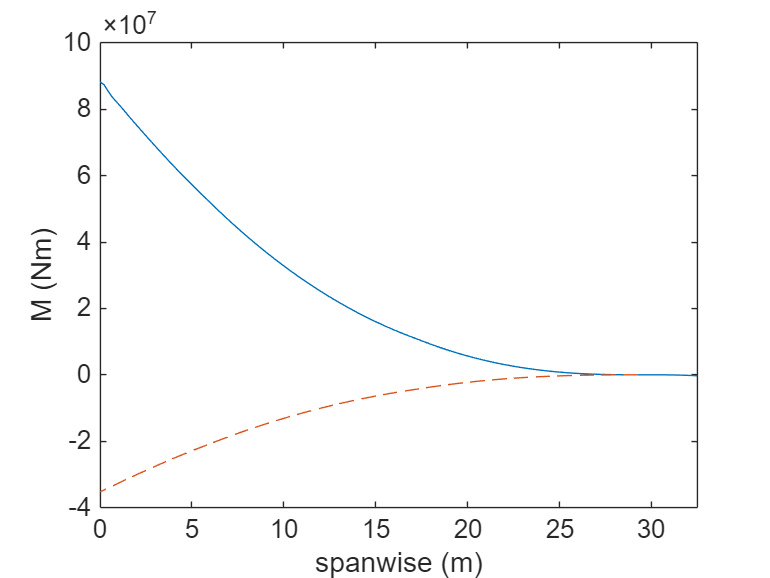

figure(pltidx)
clf;
plot(wing_opt.stripy, M)
hold on
plot(y0, M0,'--')
xlabel("spanwise (m)")
ylabel("M (Nm)")
xlim([0 wing_opt.b/2])

pltidx = pltidx + 1;

Material:

Al7068 =material(); %Aluminum 2024 T861
Al7068.E = 71.2e9; %E - 72-75.7 GPa (@23degC is 73)
Al7068.sigma_y = 648e6; %sigma_y - 400-462 MPa (@23degC is 441)
Al7068.G = 28.5e9; %G - 28-29.4 GPa
Al7068.sigma_y_tensile = 683e6;
Al7068.rho = 2850;
Al7068.price = 3.61;

Al2024 = material();
Al2024.E = 72e9; %E - 72-75.7 GPa (@23degC is 73)
Al2024.sigma_y = 400e6; %sigma_y - 400-462 MPa (@23degC is 441)
Al2024.G = 28e9; %G - 28-29.4 GPa
Al2024.sigma_y_tensile = 441e6;
Al2024.rho = 2780;
Al2024.price = 1.88;

## **WingBox geometry (unchanged throughout)**

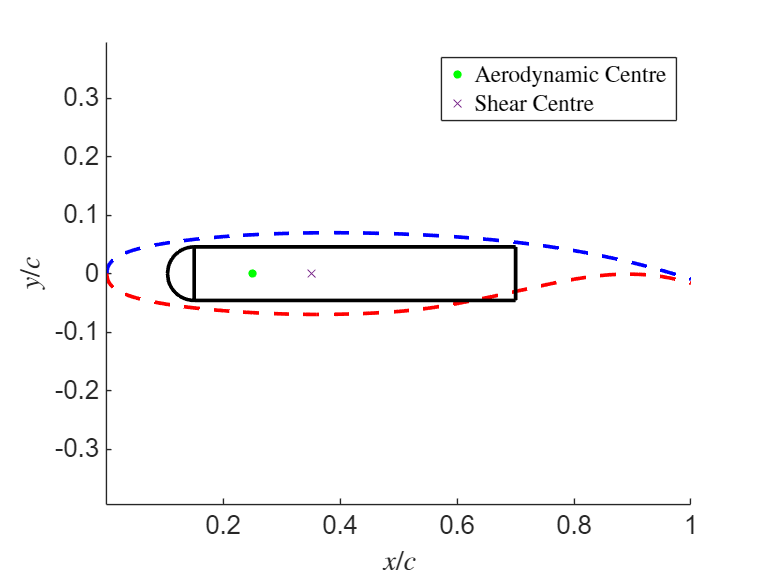

D = 6.38;
wb = wingbox();
%define geometry
wb.b2_c = mean(airfoil.uppershape(:,2) - airfoil.lowershape(:,2));
wb.b_c = 0.15;
wb.c_c = 0.7 - wb.b_c;
%wb = wb.calcR();
wb.R_c = wb.b2_c/2;
%define stringers
wb.L = 1;
%show wingbox:
figure(1)
clf;
wb.drawwithAirfoil(airfoil)
hold on
scatter((wb.b_c + wb.c_c)/2,0,'x')
legend("","","Aerodynamic Centre","","","","","","","","Shear Centre","Interpreter","latex")
xlabel("$x/c$","Interpreter","latex")
ylabel("$y/c$","Interpreter","latex")
print(gcf, fullfile('images', 'wingbox.png'), '-dpng', '-r300');

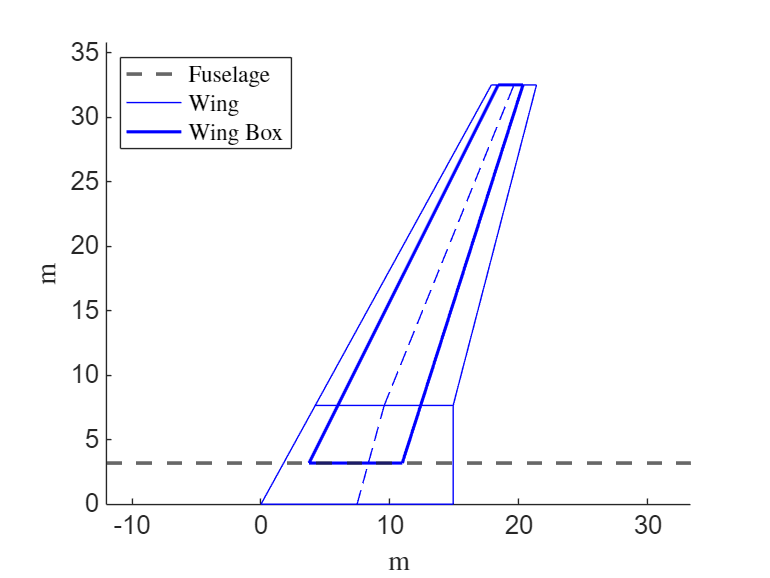


figure(2)
clf;
yline(D/2,'--','LineWidth',2)
hold on
wing_opt.plotWing()
hold on
wb.plotWingBox(wing_opt,D)
axis equal
ylim([0 wing_opt.b/2*1.1])
legend("Fuselage","","","","","","","","","","","","","","","","Wing","","","","","Wing Box","Location","northWest","Interpreter","latex")
xlabel("m","Interpreter","latex")
ylabel("m","Interpreter","latex")
print(gcf, fullfile('images', 'wingboxTopView.png'), '-dpng', '-r300');



wb = wb.calcCellArea(wing_opt);
%define rib spacing
wb.a = ones(1,length(wing_opt.stripy)).*5;
wingidx = find(wing_opt.stripy > D/2); % only consider points on the wing

## 1.UpperPanel Design

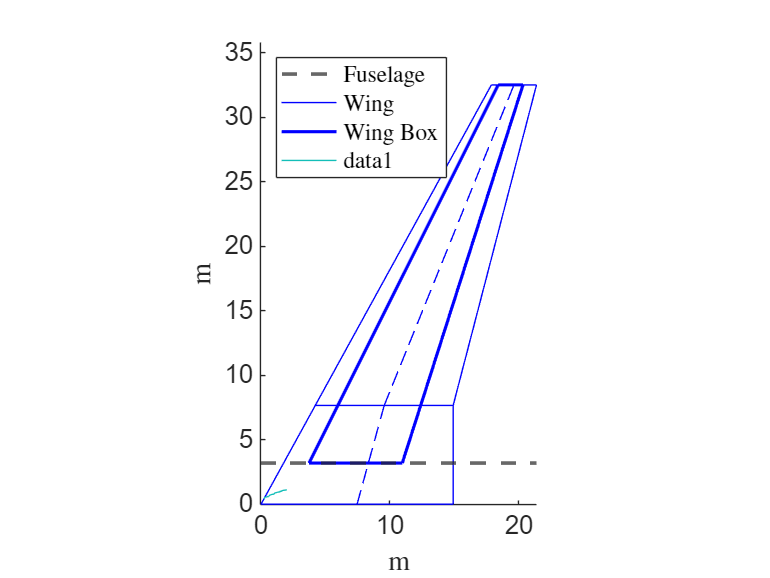

As_bt_vals =     0.2498    0.2580    0.2638    0.2683    0.2719    0.2737    0.2759    0.2873    0.3280    0.3688    0.3696    0.4012    0.4095    0.4502    0.4910    0.5033    0.5317    0.5724    0.5971    0.6132    0.6224    0.6369    0.6539    0.6542    0.6680    0.6851    0.6946    0.7354    0.7441    0.7761    0.7974    0.8168    0.8576    0.8983    0.9080    0.9390    0.9798    0.9833    1.0190    1.0205    1.0385    1.0577    1.0612    1.0794    1.1020    1.1309    1.1427    1.1834    1.2106    1.2242


ts_t_vals =     0.4000    0.4204    0.4408    0.4612    0.4816    0.5020    0.5224    0.5381    0.5401    0.5421    0.5429    0.5633    0.5667    0.5755    0.5818    0.5837    0.5888    0.5977    0.6041    0.6127    0.6245    0.6449    0.6649    0.6653    0.6857    0.7061    0.7152    0.7209    0.7265    0.7436    0.7469    0.7497    0.7558    0.7659    0.7673    0.7719    0.7862    0.7878    0.8082    0.8094    0.8286    0.8490    0.8527    0.8694    0.8860    0.8898    0.8913    0.8996    0.9102    0.9156


% Precompute parameters
c = wb.c_c .* wing_opt.cn;
b2 = wb.b2_c .* wing_opt.cn;
N = M ./ c ./ b2;
E = Al7068.E;
sigmaY = Al7068.sigma_y;
Nneg = Mneg ./ c ./ b2;

% Initialize optimal parameter vectors
bestt = zeros(size(wing_opt.stripy));
besths = zeros(size(wing_opt.stripy));

[As_bt_vals, ts_t_vals] = findAsbt_ts_for_fb_f0(1, 50, 50)

bestF = 0;
for i = 1:length(As_bt_vals)
    F = interpF(As_bt_vals(i), ts_t_vals(i));
    if F > bestF
        bestF = F;
        As_bt = As_bt_vals(i);
        ts_t = ts_t_vals(i);
    end
end
F = bestF;
sigma0 = sigmaY;
ts = max(0e-3,N./sigma0);
t = max(0e-3,ts./ts_t);



Assign manufacturing thickness:

%td = [0.014 0.011 0.003];
td = [0.0115 0.0115 0.0115]

td =     0.0115    0.0115    0.0115



wb.t_Upper = d2c(wing_opt,td);
wb.ts_Upper = d2c(wing_opt,td*ts_t);
function tspace = d2c(wing,t)
    yspace = wing.stripy;
    tspace = [t(3)*ones(1,50) t(2)*ones(1,50) t(1)*ones(1,50) t(1) t(1)*ones(1,50) t(2)*ones(1,50) t(3)*ones(1,50)];
end

b1 = max(0,wb.t_Upper.*sqrt(3.62*E./sigma0))

b1 =     0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294    0.2294


idealN = 1./(b1./wing_opt.cn);
Ns = [ceil(idealN(136)) ceil(idealN(100)) ceil(idealN(50))];
wb.N = [Ns(3)*ones(1,50) Ns(2)*ones(1,50) Ns(1)*ones(1,50) Ns(1)...
    Ns(1)*ones(1,50) Ns(2)*ones(1,50) Ns(3)*ones(1,50)]

wb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: []
     b1_c_Lower: []
            b_c: 0.1500
            R_c: 0.0457
              a: [5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 … ] (1×301 double)
           b2_c: 0.0915
       ts_Upper: [0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0123 0.0

wb.b1_c = 1./wb.N;
sigma0 = N./wb.t_Upper;
sigma0(sigma0 < 0) = NaN;
%vary hs to find optimum
d_hratio = 0.3;
hsval = linspace(1e-3, 400e-3, 400)

hsval =     0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


besterr = Inf;
besths = 0;

for i = 1:length(hsval)
    hs = hsval(i).*ones(size(wing_opt.stripy));
    As = wb.ts_Upper.*hs.*(1 + 2*d_hratio);
    xq = As ./ (wb.b1_c .* wing_opt.cn) ./ wb.t_Upper;
    err = abs(mean(xq)-As_bt);
    if err < besterr && max(xq) <2
       besths = hsval(i);
       besterr = err;
    end
end
besths

besths = 0.1410

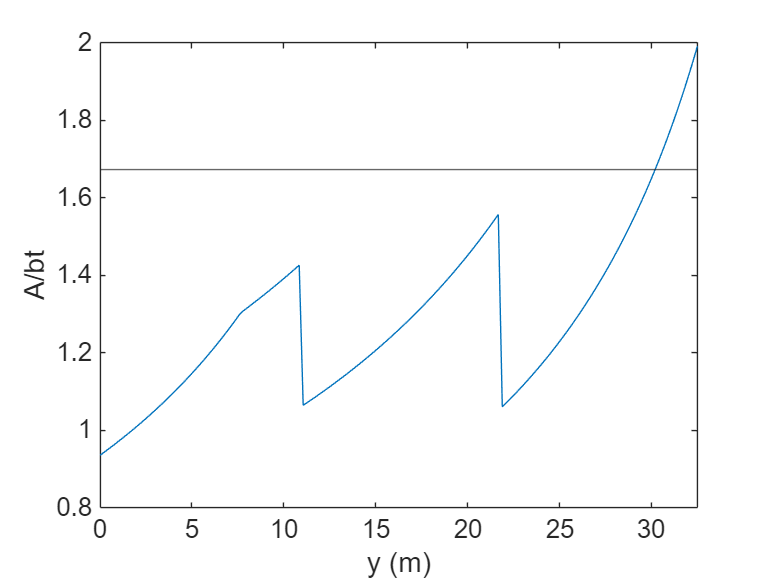

wb.hs = besths;
wb.ds = wb.hs*d_hratio;
wb = wb.calcStringerArea();

As_opt = wb.ts_Upper .* wb.hs .* (1 + 2*d_hratio);
xq_opt = As_opt ./ (wb.b1_c .* wing_opt.cn) ./ wb.t_Upper;

figure(1)
clf;
plot(wing_opt.stripy, xq_opt)
hold on
yline(As_bt)
ylabel("A/bt")
xlabel("y (m)")
xlim([0 wing_opt.b/2])

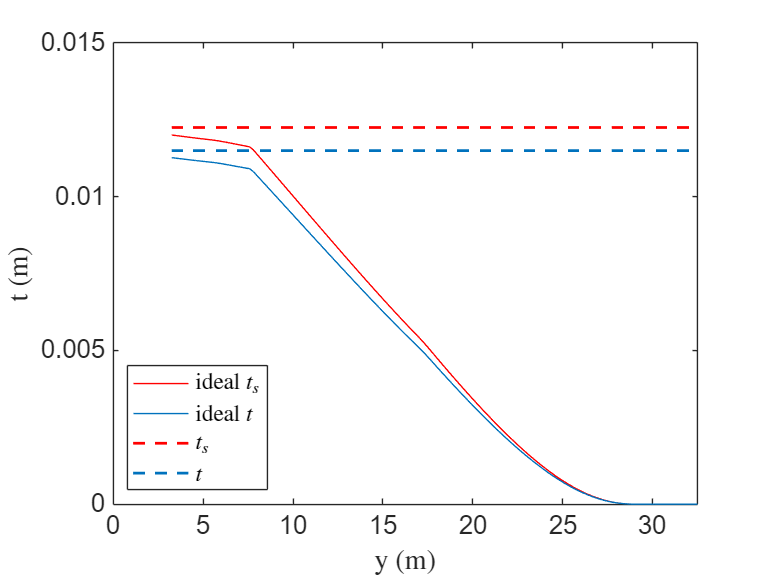


figure(2)
clf;
plot(wing_opt.stripy(wingidx),ts(wingidx),'r')
hold on
plot(wing_opt.stripy(wingidx),t(wingidx),'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy(wingidx), wb.ts_Upper(wingidx),'r--','LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx), wb.t_Upper(wingidx), 'Color', [0 0.4470 0.7410], 'LineStyle', '--', 'LineWidth', 1.5)


xlim([0, wing_opt.b/2])
ylabel("t (m)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
ylim([0 0.015])
legend("ideal $t_s$", "ideal $t$","$t_s$","$t$","Interpreter","latex","Location","southwest")
print(gcf, fullfile('images', 'Uplate_t.png'), '-dpng', '-r300');

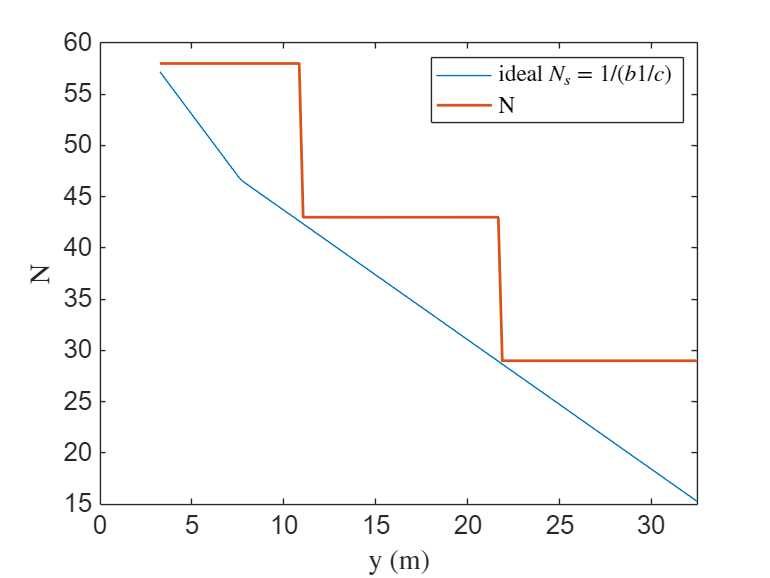


figure(3)
clf;
plot(wing_opt.stripy(wingidx), 1./(b1(wingidx)./wing_opt.cn(wingidx)))
hold on
plot(wing_opt.stripy(wingidx), 1./wb.b1_c(wingidx),'LineWidth',1.5)

xlim([0, wing_opt.b/2])
ylabel("N","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
legend("ideal $N_s = 1/(b1/c)$","N","Interpreter","latex")
print(gcf, fullfile('images', 'Uplate_N.png'), '-dpng', '-r300');


% figure(7)
% hold on
% plot(wing_opt.stripy(wingidx), 1./wb.b1_c(wingidx)./(wing_opt.cn(wingidx).*wb.c_c),'LineWidth',1.5)
% xlim([0, wing_opt.b/2])
% ylabel("Number of stringers per metre","Interpreter","latex")
% xlabel("y (m)","Interpreter","latex")
% legend("Constant thickness","Vary thickness","Interpreter","latex")
% print(gcf, fullfile('images', 'installDensity.png'), '-dpng', '-r300');


wb = wb.interpsr_s0(scr_s0,wing_opt);
wb = wb.interpretF(F_data, wing_opt);
idealL = N.*E.*(sigma0./F).^(-2);
wb.L = min(idealL*0.38, 10)

wb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 … ] (1×301 double)
     b1_c_Lower: []
            b_c: 0.1500
            R_c: 0.0457
              a: [5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 



[wb.yrib, wb.Nrib] = createRibLocationsFromL(wb.L, wing_opt, D);

figure(4)
clf;
plot(wing_opt.stripy(wingidx), wb.L(wingidx),'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy(wingidx),idealL(wingidx),'Color', [0 0.4470 0.7410], 'LineStyle', '--')
hold on
wb = wb.mapRibSpacing(wing_opt,D)

wb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 … ] (1×301 double)
     b1_c_Lower: []
            b_c: 0.1500
            R_c: 0.0457
              a: [5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 

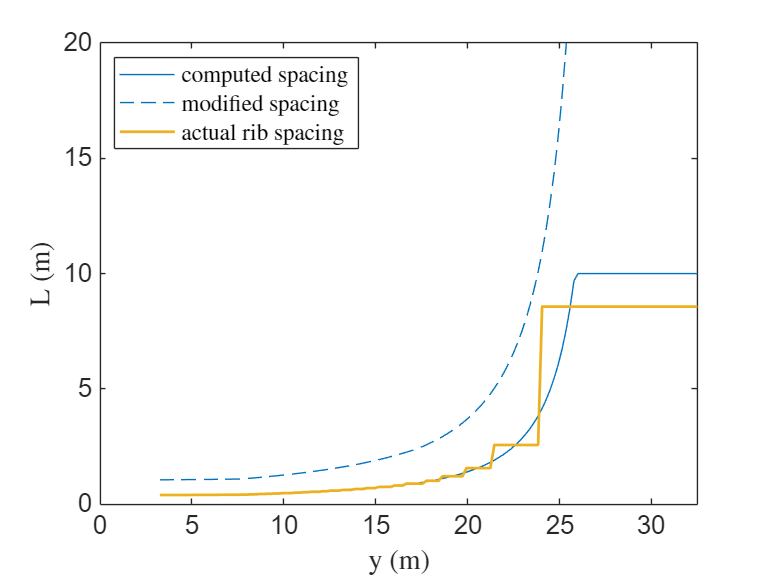

plot(wing_opt.stripy(wingidx), wb.L(wingidx),'LineWidth',1.5)

xlim([0, wing_opt.b/2])
ylim([0 20])
ylabel("L (m)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
legend("computed spacing","modified spacing","actual rib spacing","Interpreter","latex","Location","northwest")
print(gcf, fullfile('images', 'RibSpacing.png'), '-dpng', '-r300');

Finally display stress

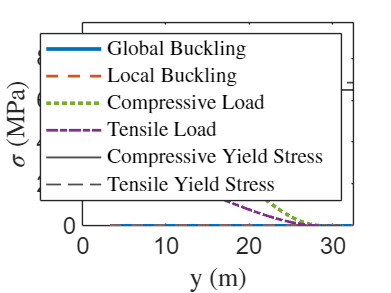

pltidx = 1;
wbStress = wingboxStress();
wbStress.wb = wb;
wbStress = wbStress.findGlobalStress(M,wing_opt,Al7068, wb.t_Upper);
wbStress = wbStress.findLocalStress(M,wing_opt,Al7068);
stressGlobal = wb.sr_s0.*3.61.*E.*(wb.t_Upper./(wb.b1_c.*wing_opt.cn)).^2;
figure(5)
clf;
% Global Buckling: Solid Blue, Thick
plot(wing_opt.stripy(wingidx), stressGlobal(wingidx)*1e-6, ...
    'LineStyle', '-', 'Color', [0, 0.4470, 0.7410], 'LineWidth', 2);
hold on;
% Local Buckling: Dashed Orange, Medium
plot(wing_opt.stripy(wingidx), wbStress.s_cr_local_skin(wingidx)*1e-6, ...
    'LineStyle', '--', 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1.5);
% Compressive Load: Dotted Green, Thick
plot(wing_opt.stripy(wingidx), N(wingidx)./wb.t_Upper(wingidx)*1e-6, ...
    'LineStyle', ':', 'Color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2);
% Tensile Load: Dash-Dot Purple, Medium
plot(wing_opt.stripy(wingidx), -Nneg(wingidx)./wb.t_Upper(wingidx)*1e-6, ...
    'LineStyle', '-.', 'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 1.5);
% Compressive Yield: Solid Black
yline(Al7068.sigma_y*1e-6, 'LineStyle', '-', 'Color', 'k', 'LineWidth', 1);
% Tensile Yield: Dashed Black
yline(Al7068.sigma_y_tensile*1e-6, 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1);

legend("Global Buckling","Local Buckling","Compressive Load","Tensile Load",...
    "Compressive Yield Stress","Tensile Yield Stress", "Interpreter","latex");
xlabel("y (m)", "Interpreter", "latex");
ylabel("$\sigma$ (MPa)", "Interpreter", "latex");
xlim([0 wing_opt.s]);
ylim([0 Al7068.sigma_y*1e-6*1.5]);
print(gcf, fullfile('images', 'UplateStressDiagram.png'), '-dpng', '-r300');


sigmacr_Uskin = wbStress.s_cr_local_skin;
sigma_Uskin = N./wb.t_Upper;


Display rib

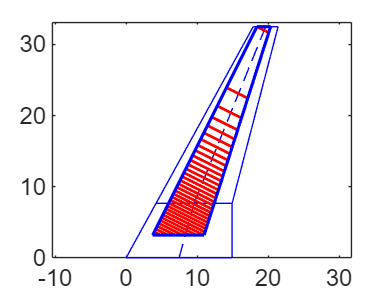

figure(6)
clf;
wing_opt.plotWing
hold on
wb.plotRibs(wing_opt)
hold on
wb.plotWingBox(wing_opt,D)
ylim([0 wing_opt.b/2*1.02])
axis equal
print(gcf, fullfile('images', 'WingandRib.png'), '-dpng', '-r300');

Lower skin

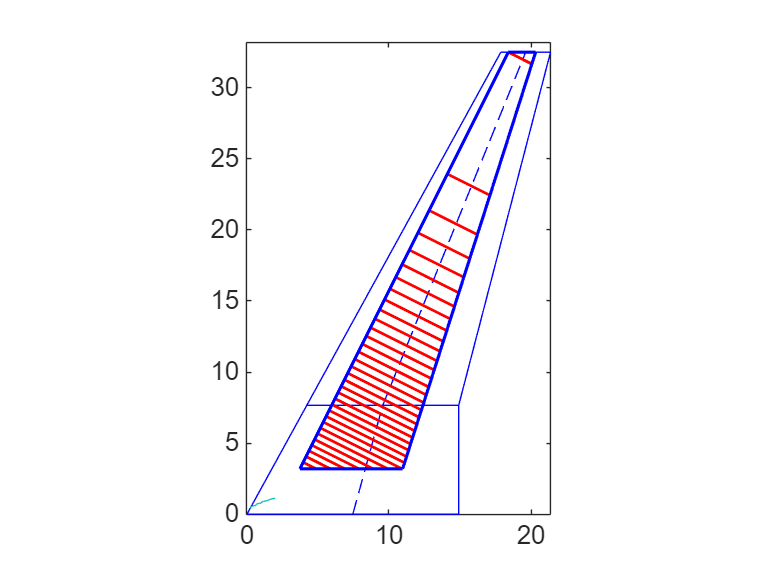

As_bt_vals =     0.2498    0.2580    0.2638    0.2683    0.2719    0.2737    0.2759    0.2873    0.3280    0.3688    0.3696    0.4012    0.4095    0.4502    0.4910    0.5033    0.5317    0.5724    0.5971    0.6132    0.6224    0.6369    0.6539    0.6542    0.6680    0.6851    0.6946    0.7354    0.7441    0.7761    0.7974    0.8168    0.8576    0.8983    0.9080    0.9390    0.9798    0.9833    1.0190    1.0205    1.0385    1.0577    1.0612    1.0794    1.1020    1.1309    1.1427    1.1834    1.2106    1.2242


ts_t_vals =     0.4000    0.4204    0.4408    0.4612    0.4816    0.5020    0.5224    0.5381    0.5401    0.5421    0.5429    0.5633    0.5667    0.5755    0.5818    0.5837    0.5888    0.5977    0.6041    0.6127    0.6245    0.6449    0.6649    0.6653    0.6857    0.7061    0.7152    0.7209    0.7265    0.7436    0.7469    0.7497    0.7558    0.7659    0.7673    0.7719    0.7862    0.7878    0.8082    0.8094    0.8286    0.8490    0.8527    0.8694    0.8860    0.8898    0.8913    0.8996    0.9102    0.9156



% Precompute parameters
c = wb.c_c .* wing_opt.cn;
b2 = wb.b2_c .* wing_opt.cn;
N = M ./ c ./ b2;
Nneg = Mneg ./ c ./ b2;
E = Al7068.E;
sigmaYT = Al7068.sigma_y_tensile;
sigmaY = Al7068.sigma_y;

% Initialize optimal parameter vectors
bestt = zeros(size(wing_opt.stripy));
besths = zeros(size(wing_opt.stripy));

[As_bt_vals, ts_t_vals] = findAsbt_ts_for_fb_f0(1, 50, 50)

bestF = 0;
for i = 1:length(As_bt_vals)
    F = interpF(As_bt_vals(i), ts_t_vals(i));
    if F > bestF
        bestF = F;
        As_bt = As_bt_vals(i);
        ts_t = ts_t_vals(i);
    end
end
F = bestF;
sigma0T = sigmaYT;
sigma0 = sigmaY;
ts = max(0e-3,N./sigma0T);
t = max(0e-3,ts./ts_t);

td = [0.011 0.011 0.011]

td =     0.0110    0.0110    0.0110


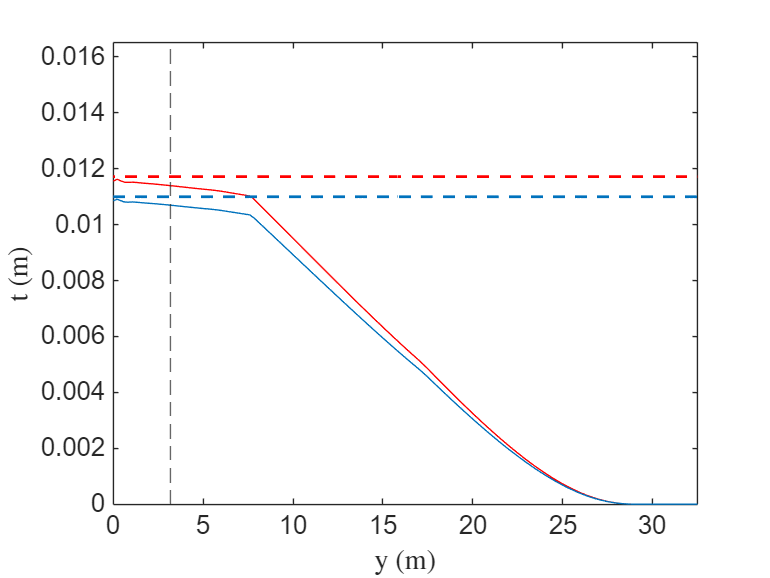


wb.t_Lower = d2c(wing_opt,td);
wb.ts_Lower = d2c(wing_opt,td*ts_t);

figure(1)
clf;
plot(wing_opt.stripy,ts,'r')
hold on
plot(wing_opt.stripy,t,'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy, wb.ts_Lower,'r--','LineWidth',1.5)
hold on
plot(wing_opt.stripy, wb.t_Lower, 'Color', [0 0.4470 0.7410], 'LineStyle', '--', 'LineWidth', 1.5)
hold on
xline(D/2,'--')
xlim([0, wing_opt.b/2])
ylabel("t (m)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
ylim([0 0.0165])

%Buckling design
b1 = max(0,wb.t_Lower.*sqrt(3.62*E./sigma0))

b1 =     0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194    0.2194


idealN = 1./(b1./wing_opt.cn);
Ns = [ceil(idealN(136)) ceil(idealN(100)) ceil(idealN(50))];
wb.N_Lower = [Ns(3)*ones(1,50) Ns(2)*ones(1,50) Ns(1)*ones(1,50) Ns(1)...
    Ns(1)*ones(1,50) Ns(2)*ones(1,50) Ns(3)*ones(1,50)]

wb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 … ] (1×301 double)
        t_Lower: [0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 … ] (1×301 double)
     b1_c_Lower: []
            b_c: 0.1500
          

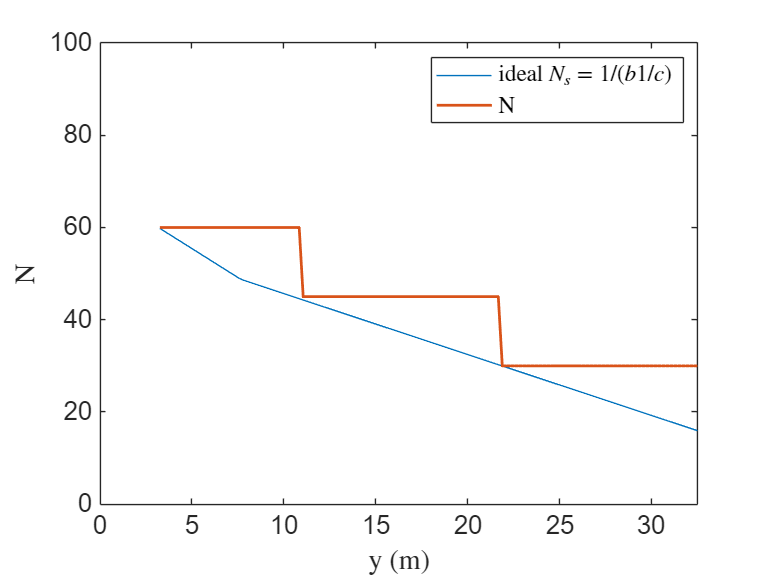

wb.b1_c_Lower = 1./wb.N_Lower;
figure(2)
clf;
plot(wing_opt.stripy(wingidx), 1./(b1(wingidx)./wing_opt.cn(wingidx)))
hold on
plot(wing_opt.stripy(wingidx), 1./wb.b1_c_Lower(wingidx),'LineWidth',1.5)

xlim([0, wing_opt.b/2])
ylim([0 100])
ylabel("N","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
legend("ideal $N_s = 1/(b1/c)$","N","Interpreter","latex")
print(gcf, fullfile('images', 'LplateN.png'), '-dpng', '-r300');

sigma0 = -Nneg./wb.t_Lower;
sigma0(sigma0 < 0) = NaN;
%vary hs to find optimum
d_hratio = 0.3;
hsval = linspace(1e-3, 400e-3, 400)

hsval =     0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


besterr = Inf;
besths = 0;

for i = 1:length(hsval)
    hs = hsval(i).*ones(size(wing_opt.stripy));
    As = wb.ts_Lower.*hs.*(1 + 2*d_hratio);
    xq = As ./ (wb.b1_c_Lower .* wing_opt.cn) ./ wb.t_Lower;
    err = abs(mean(xq)-As_bt);
    if err < besterr && max(xq) <2
       besths = hsval(i);
       besterr = err;
    end
end
besths

besths = 0.1360

wb.hs_Lower = besths;
wb.ds_Lower = wb.hs_Lower*d_hratio;
wb = wb.calcStringerArea_Lower();
As_opt = wb.ts_Lower .* wb.hs_Lower .* (1 + 2*d_hratio);
xq_opt = As_opt ./ (wb.b1_c_Lower .* wing_opt.cn) ./ wb.t_Lower;


Display stress

%1. buckling
wb = wb.interpsr_s0_Lower(scr_s0,wing_opt);
wb = wb.interpretF_Lower(F_data, wing_opt);
sglobal = wb.sr_s0_Lower.*3.62.*E.*(wb.t_Lower./(wb.b1_c_Lower.*wing_opt.cn)).^2;
slocal = wb.F_Lower.*sqrt(-Nneg.*E./wb.L);

figure(3)
clf;
% Global Buckling: Solid Blue, Thick
plot(wing_opt.stripy(wingidx), sglobal(wingidx)*1e-6, ...
    'LineStyle', '-', 'Color', [0, 0.4470, 0.7410], 'LineWidth', 2);
hold on;
% Local Buckling: Dashed Orange, Medium
plot(wing_opt.stripy(wingidx), slocal(wingidx)*1e-6, ...
    'LineStyle', '--', 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1.5);

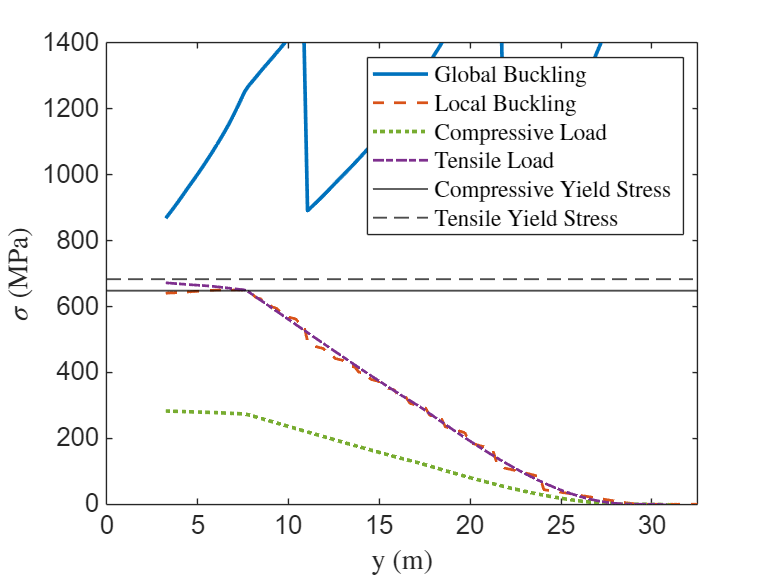

% Compressive Load: Dotted Green, Thick
plot(wing_opt.stripy(wingidx), -Nneg(wingidx)./wb.t_Lower(wingidx)*1e-6, ...
    'LineStyle', ':', 'Color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2);
% Tensile Load: Dash-Dot Purple, Medium
plot(wing_opt.stripy(wingidx), N(wingidx)./wb.t_Lower(wingidx)*1e-6*0.95, ...
    'LineStyle', '-.', 'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 1.5);
% Compressive Yield: Solid Black
yline(Al7068.sigma_y*1e-6, 'LineStyle', '-', 'Color', 'k', 'LineWidth', 1);
% Tensile Yield: Dashed Black
yline(Al7068.sigma_y_tensile*1e-6, 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1);

legend("Global Buckling","Local Buckling","Compressive Load","Tensile Load",...
    "Compressive Yield Stress","Tensile Yield Stress", "Interpreter","latex");
xlabel("y (m)", "Interpreter", "latex");
ylabel("$\sigma$ (MPa)", "Interpreter", "latex");
xlim([0 wing_opt.s]);
ylim([0 1400]);
print(gcf, fullfile('images', 'LplateStressDiagram.png'), '-dpng', '-r300');


sigmacr_Lskin = slocal;
sigma_Lskin = -Nneg./wb.t_Lower;

## **2. Rib**

%Calculate effective panel thickness of upper and lower
t_eff_upper = wb.t_Upper + wb.As./wb.b1_c./wing_opt.cn;
t_eff_lower = wb.t_Lower + wb.As_Lower./wb.b1_c_Lower./wing_opt.cn;

E = Al2024.E;
chord = wing_opt.cn;
h = wb.b2_c.*wing_opt.cn;
s = wb.a;
sigma_y = Al2024.sigma_y;

%Find moment of inertia
I_Upper = chord .* (t_eff_upper).^3 ./ 12 + chord .* (t_eff_upper) .* (h./2).^2;
I_Lower = chord .* (t_eff_lower).^3 ./ 12 + chord .* (t_eff_lower) .* (h./2).^2;

%Crush load
F = @(M,s,h,t_e,chord,E,I) (M.^2 .* s .* h .* ...
    (t_e) .* chord ./ 2) ./ ...
    (E .* I.^2);
%There are 4 combinations of crush load: pos upper, pos lower, neg upper
%and neg lower
F_pos_upper = F(M, wb.L, h, t_eff_upper, wing_opt.cn, E, I_Upper)

F_pos_upper = 1.0e+06 *

    0.0221    0.0131    0.0075    0.0041    0.0021    0.0010    0.0005    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0009    0.0015    0.0023    0.0034    0.0049    0.0069    0.0094    0.0125    0.0163    0.0210    0.0265    0.0330    0.0407    0.0495    0.0597    0.0713    0.0253    0.0297    0.0346    0.0401    0.0462    0.0529    0.0602    0.0682    0.0769    0.0864


F_neg_upper = F(Mneg, wb.L, h, t_eff_upper, wing_opt.cn, E, I_Upper)

F_neg_upper = 1.0e+05 *

    0.0645    0.0395    0.0234    0.0133    0.0072    0.0037    0.0018    0.0008    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0008    0.0014    0.0024    0.0037    0.0055    0.0079    0.0110    0.0150    0.0200    0.0261    0.0335    0.0424    0.0529    0.0651    0.0792    0.0955    0.1140    0.0404    0.0475    0.0554    0.0642    0.0739    0.0846    0.0963    0.1092    0.1231    0.1382


F_pos_lower = F(M, wb.L,h, t_eff_lower, wing_opt.cn, E, I_Lower)

F_pos_lower = 1.0e+06 *

    0.0231    0.0138    0.0079    0.0043    0.0022    0.0011    0.0005    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0009    0.0015    0.0024    0.0036    0.0052    0.0072    0.0098    0.0131    0.0171    0.0219    0.0277    0.0346    0.0426    0.0518    0.0625    0.0746    0.0265    0.0311    0.0362    0.0420    0.0483    0.0553    0.0630    0.0714    0.0805    0.0904


F_neg_lower = F(Mneg, wb.L, h, t_eff_lower, wing_opt.cn, E, I_Lower)

F_neg_lower = 1.0e+06 *

    0.0068    0.0041    0.0024    0.0014    0.0008    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0004    0.0006    0.0008    0.0012    0.0016    0.0021    0.0027    0.0035    0.0044    0.0055    0.0068    0.0083    0.0100    0.0119    0.0042    0.0050    0.0058    0.0067    0.0077    0.0089    0.0101    0.0114    0.0129    0.0145


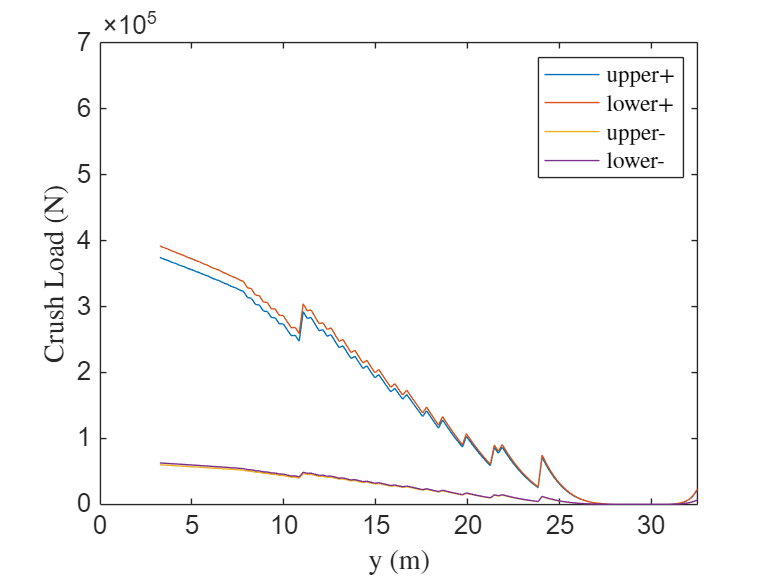

figure(1)
clf;
plot(wing_opt.stripy,F_pos_upper)
hold on
plot(wing_opt.stripy,F_pos_lower)
hold on
plot(wing_opt.stripy,F_neg_upper)
hold on
plot(wing_opt.stripy,F_neg_lower)
legend("upper+","lower+","upper-","lower-", "Interpreter", "latex")
xlim([0, wing_opt.b/2])
ylim([0, 700000])
xlabel("y (m)", "Interpreter", "latex")
ylabel("Crush Load (N)", "Interpreter", "latex")
print(gcf, fullfile('images', 'CrushDiagram.png'), '-dpng', '-r300');

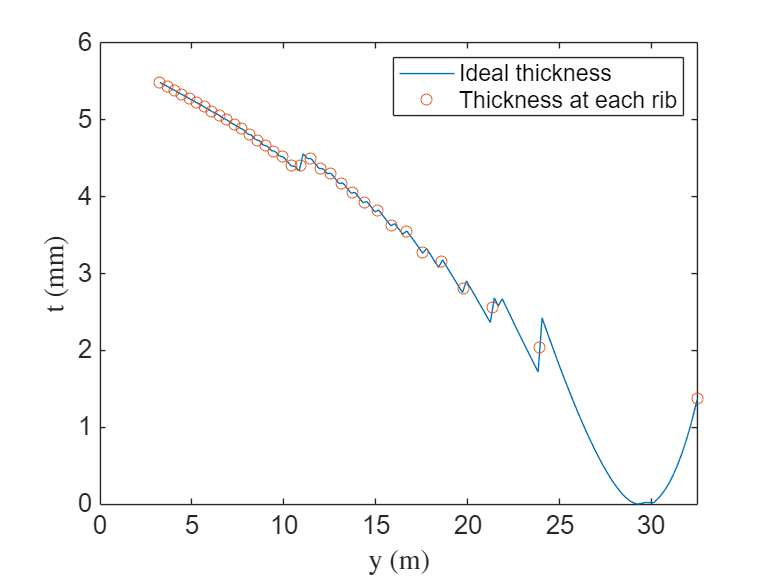

%design rib thickness
%tr = F/sigmaYc
tr1 = F_pos_lower ./ sigma_y ./ wing_opt.cn;
tr2 = sqrt(sigma_y/3.62/E).*wb.b2_c.*wing_opt.cn;
tr3 = (F_pos_lower.*h.^2./(3.62.*E.*wing_opt.cn)).^(1/3);
figure(2)
clf;
plot(wing_opt.stripy(wingidx),tr3(wingidx)*1000)
hold on
scatter(wb.yrib,interp1(wing_opt.stripy,tr3*1000,wb.yrib))

legend("Ideal thickness","Thickness at each rib")
xlim([0, wing_opt.b/2])
xlabel("y (m)", "Interpreter", "latex")
ylabel("t (mm)", "Interpreter", "latex")
print(gcf, fullfile('images', 'tr.png'), '-dpng', '-r300');


wb.tr = interp1(wing_opt.stripy,tr3,wb.yrib)

wb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 0.0115 … ] (1×301 double)
        t_Lower: [0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 0.0110 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5500
           b1_c: [0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 0.0345 … ] (1×301 double)
     b1_c_Lower: [0.0333 0.0333 0.0333 0.0333 0.0333 0

## **3. Spar buckling analysis(get spar thickness)**

**Web is fixed at top/bottom, SS at sides (web stringers)**

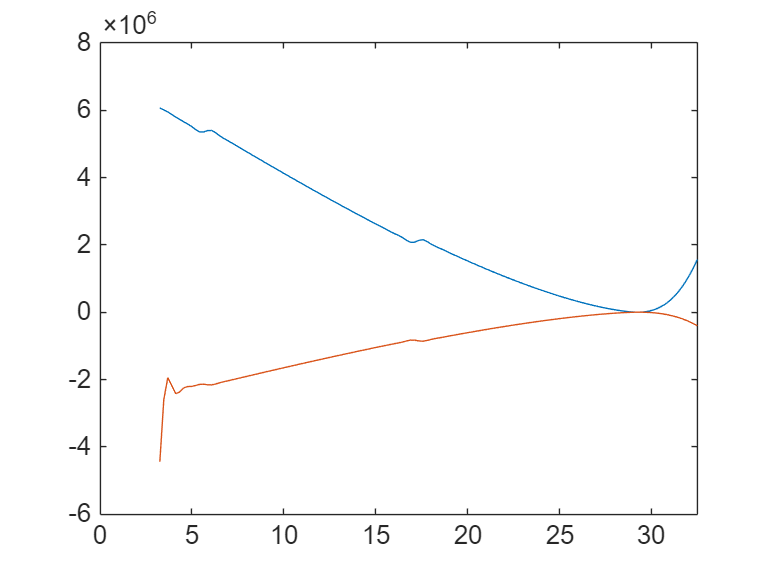

%[t_FS, t_RS] = Sparfun(wb, wing_opt,material,V,T,wbStress)

%for maximum buckling coefficient, let a = h
wb.a = wb.b2_c.*wing_opt.cn;
Ks = 8.1;
E = Al7068.E;

%Use same As/bt and ts/t
%z stringer
figure(1)
clf;
plot(wing_opt.stripy(wingidx), S(wingidx))
hold on
plot(wing_opt.stripy(wingidx), Sneg(wingidx))
xlim([0 wing_opt.b/2])

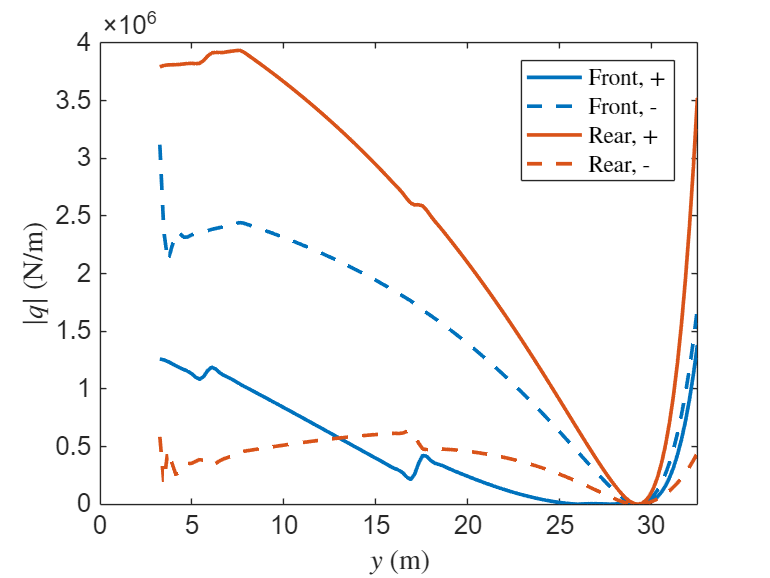


Awb = wb.c_c.*wb.b2_c.*wing_opt.cn.*wing_opt.cn;
hwb = wb.b2_c.*wing_opt.cn;

q = @(S,T,h,A) S./(2*h) + T./(2*A);

qFpos = q(-S,tau,hwb,Awb);
qFneg = q(-Sneg,tau,hwb,Awb);
qRpos = q(-S,-tau,hwb,Awb);
qRneg = q(-Sneg,-tau,hwb,Awb);

figure(2);
clf;

% Define line styles/colors for clarity
front_color = [0, 0.4470, 0.7410];  % Blue for front
rear_color = [0.8500, 0.3250, 0.0980];  % Red for rear
linewidth = 2;  % Thicker lines for visibility

% Plot front (+/-)
plot(wing_opt.stripy(wingidx), abs(qFpos(wingidx)), ...
    'Color', front_color, 'LineStyle', '-', 'LineWidth', linewidth);
hold on;
plot(wing_opt.stripy(wingidx), abs(qFneg(wingidx)), ...
    'Color', front_color, 'LineStyle', '--', 'LineWidth', linewidth);

% Plot rear (+/-)
plot(wing_opt.stripy(wingidx), abs(qRpos(wingidx)), ...
    'Color', rear_color, 'LineStyle', '-', 'LineWidth', linewidth);
plot(wing_opt.stripy(wingidx), abs(qRneg(wingidx)), ...
    'Color', rear_color, 'LineStyle', '--', 'LineWidth', linewidth);

% Formatting
legend("Front, +", "Front, -", "Rear, +", "Rear, -", ...
    'Interpreter', 'latex', 'Location', 'best');
ylabel("$\left| q \right|$ (N/m)", "Interpreter", "latex");
xlabel("$y$ (m)", "Interpreter", "latex");
xlim([0, wing_opt.b/2]);

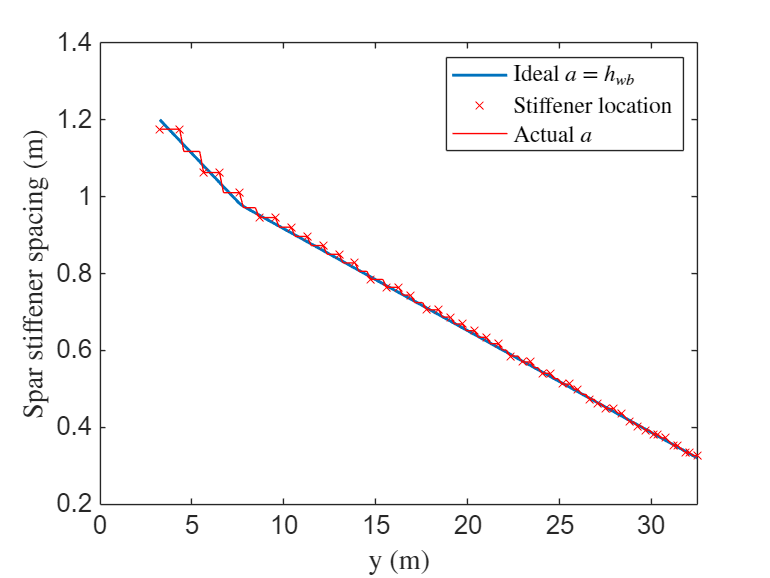

[y_spar_s, N_spar_s] = createRibLocationsFromL(wb.b2_c.*wing_opt.cn, wing_opt, D);
y_wing = wing_opt.stripy;
yrib   = y_spar_s;

% Sort yrib if not already sorted
yrib = sort(yrib);

% Pre-allocate L
L = zeros(size(y_wing));

for i = 1:length(y_wing)
    y_i = y_wing(i);

    % 1) Check if y_i is within [-D/2, D/2]
    if (y_i >= -D/2) && (y_i <= D/2)
        % If in the fuselage region, set L to NaN
        L(i) = NaN;
    else
        % 2) Otherwise, find the adjacent ribs
        k = find(yrib <= y_i, 1, 'last');

        if isempty(k)
            % y_i < yrib(1)
            L(i) = yrib(2) - yrib(1);
        elseif k == length(yrib)
            % y_i >= yrib(end)
            L(i) = yrib(end) - yrib(end-1);
        else
            % y_i lies between yrib(k) and yrib(k+1)
            L(i) = yrib(k+1) - yrib(k);
        end
    end
end

a = L;
wb.a = L;

% Initialize an array to store the indices
sparidx = NaN(size(y_spar_s)); % Use NaN for excluded points

% Loop through each point in y_spar_s
for i = 1:length(y_spar_s)
    % Find the index of the closest point in wing_opt.stripy
    [~, idx] = min(abs(wing_opt.stripy - y_spar_s(i)));
    
    % Check if the corresponding wing_opt.stripy value is within the desired range
    if abs(wing_opt.stripy(idx)) >= D/2
        sparidx(i) = idx; % Store the index if the condition is satisfied
    end
    % Otherwise, sparidx(i) remains NaN (excluded)
end



figure(3)
clf;
plot(wing_opt.stripy(wingidx), wb.b2_c.*wing_opt.cn(wingidx),'LineWidth',1.6)
hold on
scatter(wing_opt.stripy(sparidx), wb.a(sparidx),'x','r')
hold on
plot(wing_opt.stripy(wingidx), wb.a(wingidx),'r')
legend("Ideal $a$ = $h_{wb}$","Stiffener location","Actual $a$", "Interpreter", "latex")
xlabel("y (m)", "Interpreter", "latex")
ylabel("Spar stiffener spacing (m)", "Interpreter", "latex")
xlim([0 wing_opt.b/2])
print(gcf, fullfile('images', 'aspar.png'), '-dpng', '-r300');

wb.y_sparS = wing_opt.stripy(sparidx);

q_FS = abs(qFneg);
q_RS = abs(qRpos);

t_FS = (q_FS .* b2 ./ Ks ./ E).^(1/3);%thickness front spar
t_RS = (q_RS .* b2 ./ Ks ./ E).^(1/3);%thickness

tFd = [0.019 0.016 0.011]

tFd =     0.0190    0.0160    0.0110


tRd = [0.02 0.018 0.013]

tRd =     0.0200    0.0180    0.0130


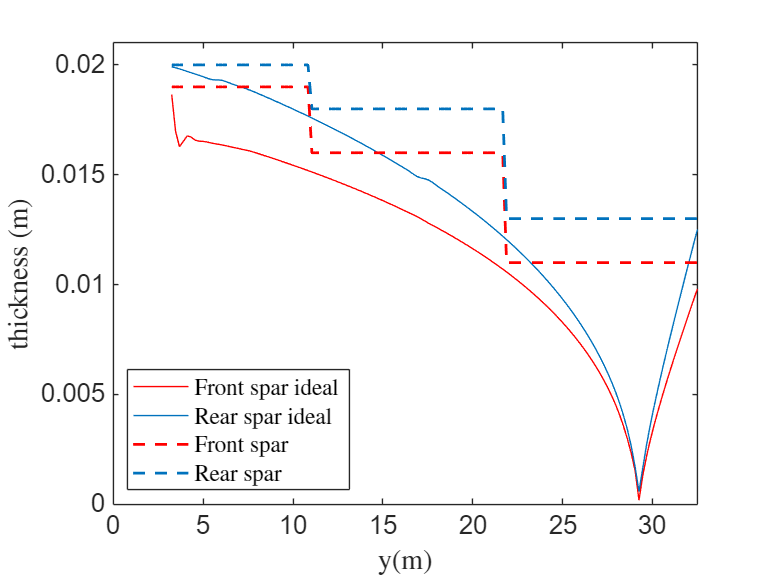


wb.tF = d2c(wing_opt,tFd);
wb.tR = d2c(wing_opt,tRd);



figure(4)
clf;
plot(wing_opt.stripy(wingidx),t_FS(wingidx),'r')
hold on
plot(wing_opt.stripy(wingidx),t_RS(wingidx),'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy(wingidx),wb.tF(wingidx),'r--','LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx),wb.tR(wingidx), 'Color', [0 0.4470 0.7410], 'LineStyle', '--', 'LineWidth', 1.5)
legend("Front spar ideal","Rear spar ideal", "Front spar","Rear spar","Location","SouthWest","Interpreter", "latex")
xlim([0, wing_opt.b/2]);
xlabel("y(m)", "Interpreter", "latex")
ylabel("thickness (m)", "Interpreter", "latex")
ylim([0 0.021])
print(gcf, fullfile('images', 'tspar.png'), '-dpng', '-r300');



t_sFS = 1.076 * wb.tF;
t_sRS = 1.076 * wb.tR;

%A = ts hs * 1.6
%hs = A / (1.6ts)

%A/at = 1.672
%A = 1.672 a t

%hs = (1.672 a t)/(1.6 ts)
h_sFS = (1.672.*wb.a.*wb.tF)./(1.6.*t_sFS)

h_sFS =     0.3171    0.3171    0.3248    0.3248    0.3343    0.3429    0.3429    0.3520    0.3620    0.3620    0.3715    0.3715    0.3814    0.3814    0.3916    0.3916    0.4022    0.4022    0.4132    0.4243    0.4243    0.4359    0.4359    0.4359    0.4477    0.4477    0.4597    0.4597    0.4720    0.4720    0.4846    0.4846    0.4980    0.4980    0.4980    0.5113    0.5113    0.5250    0.5250    0.5250    0.5393    0.5393    0.5539    0.5539    0.5539    0.5686    0.5686    0.5686    0.5841    0.5841


h_sRS = (1.672.*wb.a.*wb.tR)./(1.6.*t_sRS)

h_sRS =     0.3171    0.3171    0.3248    0.3248    0.3343    0.3429    0.3429    0.3520    0.3620    0.3620    0.3715    0.3715    0.3814    0.3814    0.3916    0.3916    0.4022    0.4022    0.4132    0.4243    0.4243    0.4359    0.4359    0.4359    0.4477    0.4477    0.4597    0.4597    0.4720    0.4720    0.4846    0.4846    0.4980    0.4980    0.4980    0.5113    0.5113    0.5250    0.5250    0.5250    0.5393    0.5393    0.5539    0.5539    0.5539    0.5686    0.5686    0.5686    0.5841    0.5841


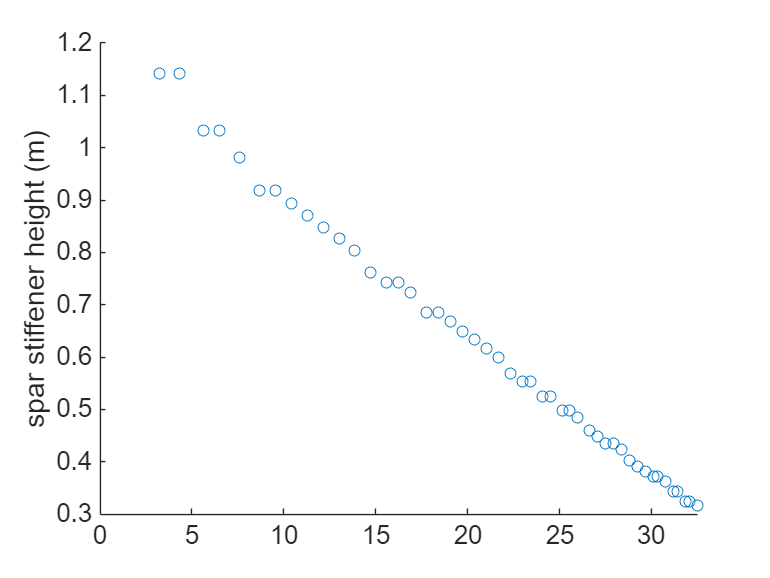

figure(5)
clf;
scatter(wing_opt.stripy(sparidx), h_sFS(sparidx))
ylabel("spar stiffener height (m)")
xlim([0 wing_opt.b/2])
print(gcf, fullfile('images', 'hss.png'), '-dpng', '-r300');


% %Verify interactive buckling in spar
% %check front spar
% tau_cr = 8.1*E.*(wb.tF./wb.a).^2;
% tau_cr_tresca = 125*1e6;
% tau_0 = qFneg./wb.tF;
% 
% Asbt_spar = t_sFS.*h_sFS*1.6./(wb.a.*t_sFS);
% ts_t_spar = 1.076;
% 
% R_c = interpsr_s0(Asbt_spar,ts_t_spar);
% R_s = tau_cr_tresca/tau_0;


## 4. Dcell

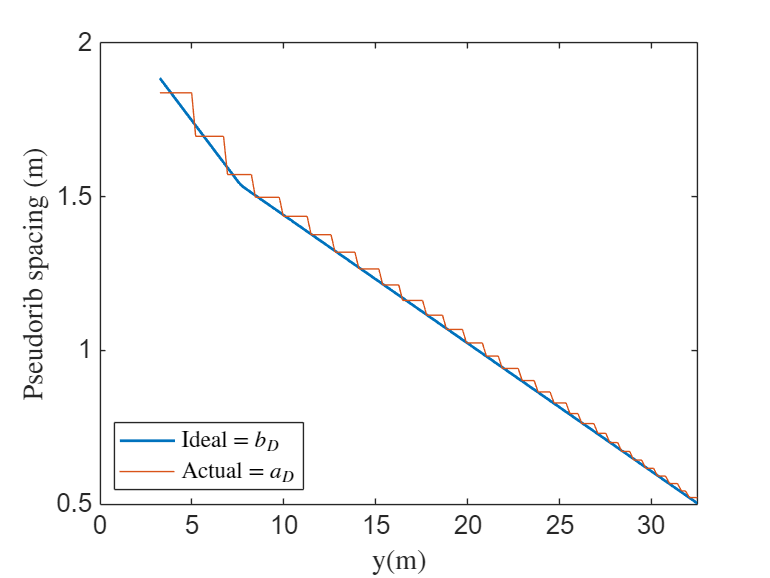

sigmaY = Al7068.sigma_y_tensile;
sigma_yield_tens = Al7068.sigma_y_tensile; % [Pa] From your material data
E = Al7068.E;                              % [Pa] Young’s modulus
b_D = pi * wb.R_c .* wing_opt.cn;          % [m] D-cell circumference (already computed)
[yprib, Nprib] = createRibLocationsFromL(b_D, wing_opt, D);

y_wing = wing_opt.stripy;
yrib   = yprib;

% Sort yrib if not already sorted
yrib = sort(yrib);

% Pre-allocate L
L = zeros(size(y_wing));

for i = 1:length(y_wing)
    y_i = y_wing(i);

    % 1) Check if y_i is within [-D/2, D/2]
    if (y_i >= -D/2) && (y_i <= D/2)
        % If in the fuselage region, set L to NaN
        L(i) = NaN;
    else
        % 2) Otherwise, find the adjacent ribs
        k = find(yrib <= y_i, 1, 'last');

        if isempty(k)
            % y_i < yrib(1)
            L(i) = yrib(2) - yrib(1);
        elseif k == length(yrib)
            % y_i >= yrib(end)
            L(i) = yrib(end) - yrib(end-1);
        else
            % y_i lies between yrib(k) and yrib(k+1)
            L(i) = yrib(k+1) - yrib(k);
        end
    end
end

wb.a_D = L;

figure(1)
clf;
plot(wing_opt.stripy(wingidx),b_D(wingidx),'LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx),wb.a_D(wingidx))
legend("Ideal = $b_D$","Actual = $a_D$","Location","SouthWest","Interpreter", "latex")
xlim([0, wing_opt.b/2]);
xlabel("y(m)", "Interpreter", "latex")
ylabel("Pseudorib spacing (m)", "Interpreter", "latex")
print(gcf, fullfile('images', 'pseudorib.png'), '-dpng', '-r300');


wb.Nprib =58; 

a_D = wb.a_D;
b_D = pi*wb.R_c.*wing_opt.cn;
R = wb.R_c.*wing_opt.cn;
taumax = sigmaY/2;

%initial guess
t1 = 20e-3*ones(size(wing_opt.stripy));
t2 = 20e-3*ones(size(wing_opt.stripy));
converged = false

converged = logical
   0


iter = 0 

iter = 0

maxiter = 6

maxiter = 6

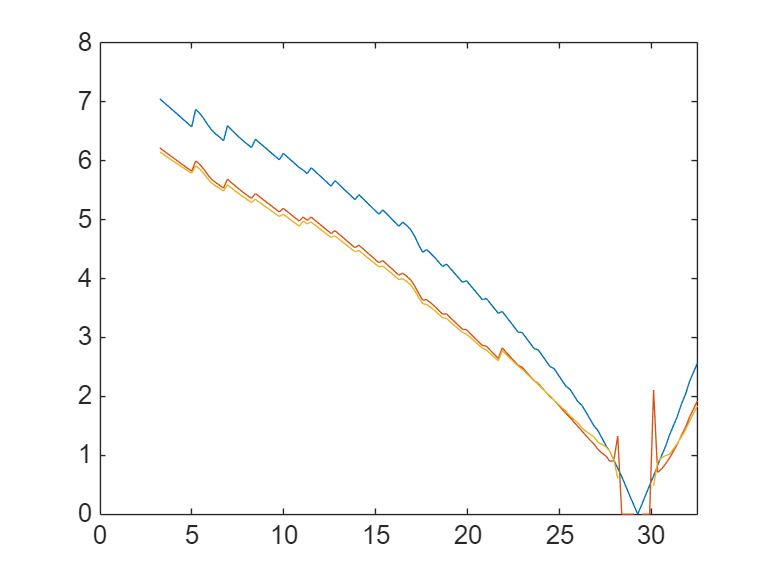

    0.0071



    0.0062



Converged


    0.0061



figure
while converged == false && iter < maxiter
    q_D = [];
    t1 = real(t2);
    for j =1:length(wingidx)
        i = wingidx(j);
        [~, q_D(i)] = shearFlow(wing_opt.cn(i), wb, tau(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), t1(i));
        %shear stress = q / t = buckling shear stress
    end
    b_RT = b_D./sqrt(R.*t1);
    b_RT = b_RT(wingidx);
    Ks = [];
    for j =1:length(wingidx)
        i = wingidx(j);
        Ks(i) = interpKspolyfit(R(i),t1(i),a_D(i),b_D(i));
    end
    %t2 = q_D./(Ks.*E.*t1.^2./b_D.^2);
    t2 = b_D.*sqrt((q_D./t1)./(Ks.*E));
    if abs(max(t2) - max(t1)) < 1e-4
        converged = true;
        disp("Converged")
    end
    plot(wing_opt.stripy(wingidx),t2(wingidx)*1000)
    hold on
    iter = iter + 1;
    disp(max(t2))
    %converged = true
end

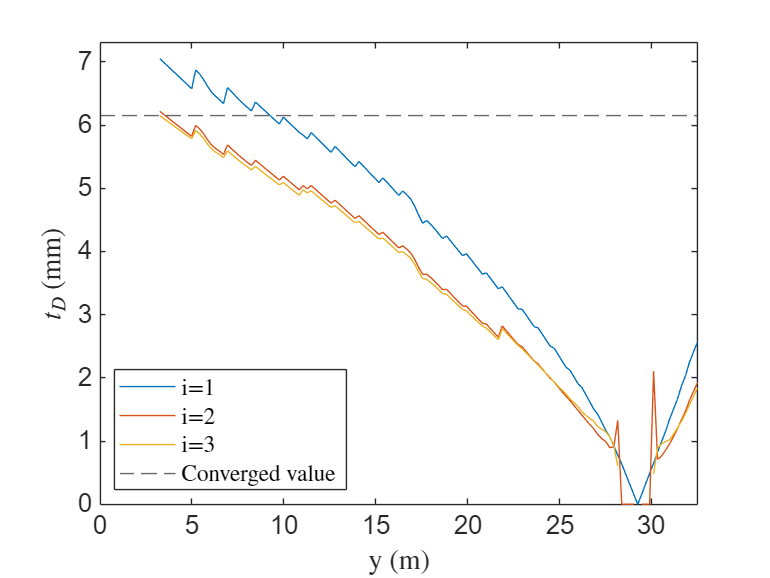

hold on
yline(max(t2)*1000,'--')
xlabel("y (m)","Interpreter","latex")
ylabel("$t_D$ (mm)","Interpreter","latex")
legend("i=1","i=2","i=3","Converged value","Interpreter","Latex","Location","SouthWest")
wb.tD = max(t2);
wb.tr_D = 3e-3;
ylim([0 7.3])

%print(gcf, fullfile('images', 'tD.png'), '-dpng', '-r300');

Interactive Buckling

Verify for upper and lower skin, front and rear spar

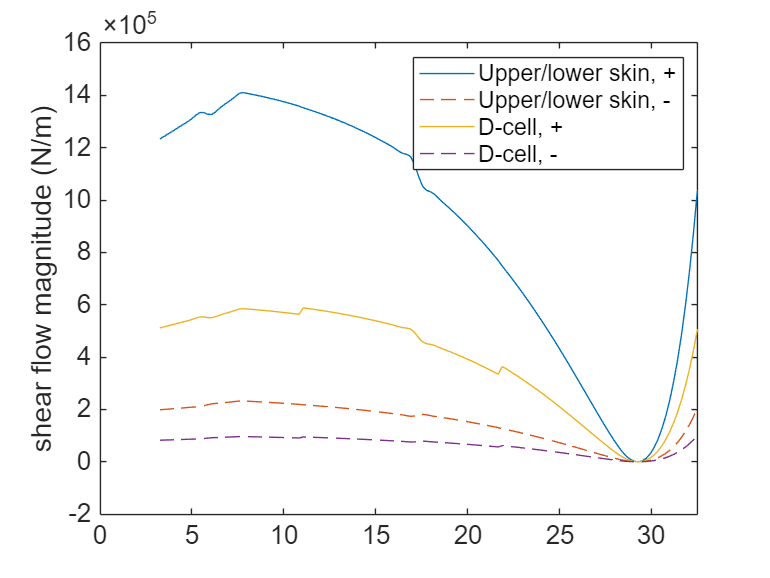

qF = -S./(2.*wb.b2_c.*wing_opt.cn);
qFneg = -Sneg./(2.*wb.b2_c.*wing_opt.cn);



q_wb = [];
q_D = [];
q_wbneg = [];
q_Dneg = [];
for j = 1:length(wingidx)
    i = wingidx(j);
    [q_wb(i), q_D(i)] = shearFlow(wing_opt.cn(i), wb, tau(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), wb.tD);
    [q_wbneg(i), q_Dneg(i)] = shearFlow(wing_opt.cn(i), wb, tauneg(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), wb.tD);
end



figure(1)
clf;
plot(wing_opt.stripy(wingidx),q_wb(wingidx))
hold on
plot(wing_opt.stripy(wingidx),abs(q_wbneg(wingidx)),'--')
hold on
plot(wing_opt.stripy(wingidx),abs(q_D(wingidx)))
hold on
plot(wing_opt.stripy(wingidx),abs(q_Dneg(wingidx)),'--')
legend("Upper/lower skin, +","Upper/lower skin, -","D-cell, +","D-cell, -")
ylabel("shear flow magnitude (N/m)")
xlim([0 wing_opt.b/2])


sigmacrs = Al7068.sigma_y_tensile./2;

%in upper skin, q_wb
RcU = sigma_Uskin./sigmacr_Uskin

RcU =    0.0000 + 0.7488i   0.0000 + 0.6523i   0.0000 + 0.5631i   0.0000 + 0.4807i   0.0000 + 0.4047i   0.0000 + 0.3349i   0.0000 + 0.2710i   0.0000 + 0.2129i   0.0000 + 0.1602i   0.0000 + 0.1126i   0.0000 + 0.0694i   0.0000 + 0.0266i   0.0292 + 0.0000i   0.0300 + 0.0000i   0.0185 + 0.0000i   0.0000 + 0.0058i   0.0213 + 0.0000i   0.0493 + 0.0000i   0.0805 + 0.0000i   0.1146 + 0.0000i   0.1507 + 0.0000i   0.1883 + 0.0000i   0.2270 + 0.0000i   0.2665 + 0.0000i   0.3067 + 0.0000i   0.3474 + 0.0000i   0.3885 + 0.0000i   0.4299 + 0.0000i   0.4717 + 0.0000i   0.5144 + 0.0000i   0.5572 + 0.0000i   0.6003 + 0.0000i   0.6430 + 0.0000i   0.6833 + 0.0000i   0.7234 + 0.0000i   0.7646 + 0.0000i   0.8063 + 0.0000i   0.8479 + 0.0000i   0.8894 + 0.0000i   0.9306 + 0.0000i   0.5318 + 0.0000i   0.5541 + 0.0000i   0.5764 + 0.0000i   0.5986 + 0.0000i   0.6209 + 0.0000i   0.6431 + 0.0000i   0.6652 + 0.0000i   0.6872 + 0.0000i   0.7091 + 0.0000i   0.7308 + 0.0000i


RsU = q_wb./wb.t_Upper./sigmacrs

RsU =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%in lower skin, q_wb
RcL = sigma_Lskin./sigmacr_Lskin

RcL =    0.0000 + 0.5698i   0.0000 + 0.5000i   0.0000 + 0.4353i   0.0000 + 0.3754i   0.0000 + 0.3202i   0.0000 + 0.2694i   0.0000 + 0.2229i   0.0000 + 0.1806i   0.0000 + 0.1424i   0.0000 + 0.1082i   0.0000 + 0.0780i   0.0000 + 0.0520i   0.0000 + 0.0306i   0.0000 + 0.0142i   0.0000 + 0.0048i   0.0042 + 0.0000i   0.0172 + 0.0000i   0.0339 + 0.0000i   0.0539 + 0.0000i   0.0763 + 0.0000i   0.1005 + 0.0000i   0.1256 + 0.0000i   0.1515 + 0.0000i   0.1778 + 0.0000i   0.2046 + 0.0000i   0.2318 + 0.0000i   0.2597 + 0.0000i   0.2878 + 0.0000i   0.3162 + 0.0000i   0.3444 + 0.0000i   0.3714 + 0.0000i   0.3983 + 0.0000i   0.4262 + 0.0000i   0.4541 + 0.0000i   0.4820 + 0.0000i   0.5099 + 0.0000i   0.5377 + 0.0000i   0.5654 + 0.0000i   0.5930 + 0.0000i   0.6204 + 0.0000i   0.3546 + 0.0000i   0.3696 + 0.0000i   0.3847 + 0.0000i   0.3996 + 0.0000i   0.4145 + 0.0000i   0.4293 + 0.0000i   0.4440 + 0.0000i   0.4586 + 0.0000i   0.4732 + 0.0000i   0.4877 + 0.0000i


RsL = q_wb./wb.t_Lower./sigmacrs

RsL =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



xspace = linspace(0,1,100);
figure(2)
clf;
scatter(RcU(wingidx),RsU(wingidx),'x')

hold on
scatter(RcL(wingidx),RsL(wingidx),'.')

hold on
plot(xspace, sqrt(0.99-xspace),'k','LineWidth',1.5)

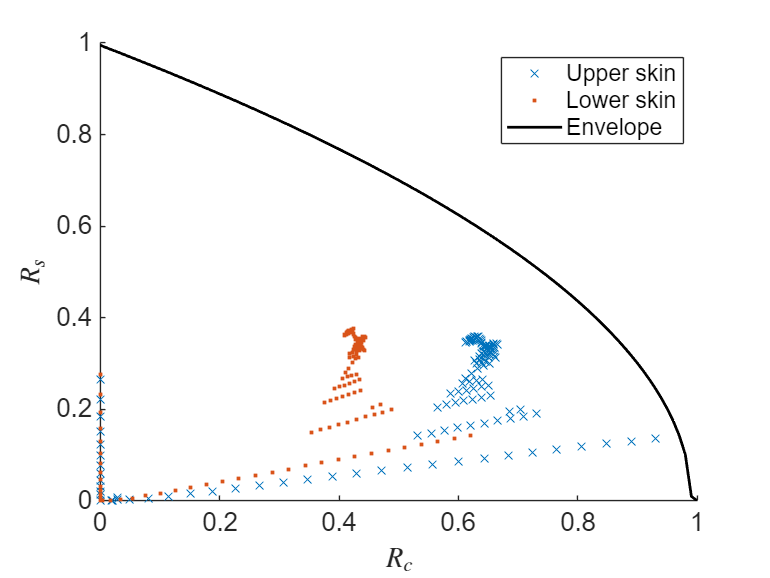

xlabel("$R_c$","Interpreter","latex")
ylabel("$R_s$","Interpreter","latex")
legend("Upper skin","Lower skin","Envelope")
print(gcf, fullfile('images', 'Interactive Buckling.png'), '-dpng', '-r300');


%find index that RcU + RsU^2 > 0.99
idx = find(RcU + RsU.^2 > 0.99);
wing_opt.stripy(idx)

ans = -3.2500

Mass Analysis

dy = wing_opt.stripy(2) - wing_opt.stripy(1);
%1. upper skin = skin + stringers
rho_Uskin = Al7068.rho;
V_Uskin = 2*trapz(wing_opt.stripy(wingidx), wb.t_Upper(1)*wb.c_c.*wing_opt.cn(wingidx)); %plate
As_Upper = mean(wb.ts_Upper).*wb.hs.*(1 + 2*0.3);
N1 = wb.N(169);
N2 = wb.N(205);
N3 = wb.N(289);
[L1, L2, L3] = getStringerLengths(wb.N, wing_opt.stripy, D);
V_Uskin_skin = V_Uskin

V_Uskin_skin = 2.8944

V_Uskin_stringer = 2*(L1*N1*As_Upper + L2*N2*As_Upper + L3*N3*As_Upper)

V_Uskin_stringer = 6.6572

V_Uskin_total = V_Uskin + V_Uskin_stringer

V_Uskin_total = 9.5516


%2. lower skin
rho_Lskin = Al7068.rho;
V_Lskin = 2*trapz(wing_opt.stripy(wingidx), wb.t_Lower(1)*wb.c_c.*wing_opt.cn(wingidx) ); %plate
As_Lower = mean(wb.ts_Lower).*wb.hs_Lower.*(1 + 2*0.3);
N1 = wb.N_Lower(169);
N2 = wb.N_Lower(205);
N3 = wb.N_Lower(289);
[L1, L2, L3] = getStringerLengths(wb.N_Lower, wing_opt.stripy, D);
V_Lskin_skin = V_Lskin

V_Lskin_skin = 2.7686

V_Lskin_stringer = 2*(L1*N1*As_Lower + L2*N2*As_Lower + L3*N3*As_Lower)

V_Lskin_stringer = 6.3817

V_Lskin = V_Lskin + V_Lskin_stringer

V_Lskin = 9.1503


%3. ribs
crib = [];
for i = 1:length(wb.yrib)
    crib(i) = wing_opt.c_at_y(wb.yrib(i));
end
Ar = (wb.c_c .* wb.b2_c .*crib.^2)

Ar =     0.6164    1.8009    2.2762    2.5938    2.8539    3.0818    3.2895    3.4845    3.6693    3.8459    4.0155    4.1792    4.3378    4.4918    4.6418    4.7884    4.9318    5.0723    5.2103    5.3459    5.4794    5.6110    5.7408    5.9724    6.2224    6.4766    6.7349    6.9972    7.2637    7.5346    7.8099    8.0893    8.3730    8.6608    8.6608    8.3730    8.0893    7.8099    7.5346    7.2637    6.9972    6.7349    6.4766    6.2224    5.9724    5.7408    5.6110    5.4794    5.3459    5.2103


V_ribs = sum(wb.tr.* Ar')

V_ribs = 1.6697


%4. front spar
ywing = wing_opt.stripy(wingidx);
tFwing = wb.tF(wingidx);
hF = [];
for i = 1:length(ywing)
    hF(i) = wb.b2_c.*wing_opt.c_at_y(ywing(i));
end
V_FS = trapz(ywing, hF.*tFwing)*2;
As_FS = h_sFS(wingidx).*t_sFS(wingidx).*(1 + 0.3*2);

V_FS_skin = V_FS

V_FS_skin = 0.6676

V_FS_stiffeners =  trapz(ywing,As_FS)*2

V_FS_stiffeners = 1.1219

V_FS = V_FS  +V_FS_stiffeners

V_FS = 1.7894



%5. rear spar
tRwing = wb.tR(wingidx);
V_RS = trapz(ywing, hF.*tRwing);
As_RS = h_sRS(wingidx).*t_sRS(wingidx).*(1 + 0.3*2);
V_RS_skin = V_RS

V_RS_skin = 0.3678

V_RS_stiffeners =  trapz(ywing,As_RS)*2

V_RS_stiffeners = 1.2362

V_RS = V_RS  +V_RS_stiffeners

V_RS = 1.6039


%6. D cell
V_D = trapz(ywing, wb.tD.*pi.*wb.R_c.*wing_opt.cn(wingidx))*2;
V_D = V_D + sum(wb.tr_D.*1/2.*pi*(wb.R_c.*wing_opt.cn(wingidx)).^2)*2

V_D = 0.5870